# Knowledge-informed Data-Driven Modeling to Identify Key Factors Governing Microbial Inactivation Processes in Food 

#### Steve Zhang, Firnaaz Ahamed, Hyun-Seob Song

#### University of Nebraska–Lincoln, Lincoln, NE

This live script walks through the process of importing the data used in the manuscript, the creation of a model that defines its functional terms and balances its accuracy and sparsity, comparing its performance against those found in the literature that had produced the datasets, evaluating the influence on the predictions individual process variables and their interactions with other process variables have on the output.

## Data incorporation

The data has been aggregated into a single Excel file. The first three sheets contain the datasets of interest and the last contains a legend explaining what each variable refers to. 

warning('off','MATLAB:rankDeficientMatrix')
addpath(genpath(pwd)); %This section uses methods located in subfolders
EveryDataset = [struct('Table',readtable('ExperimentalDataset.xlsx','Sheet',1), 'Title', "Cerf et al. (1996)", 'Name', "Cerf"),...
struct('Table', readtable('ExperimentalDataset.xlsx','Sheet',2), 'Title', "Juneja et al. (1995)", 'Name', "Juneja"),...
struct('Table', readtable('ExperimentalDataset.xlsx','Sheet',3), 'Title', "Villa-Rojas et al. (2013)", 'Name', "Villa-Rojas")];

EveryDataset(2).Table.CN = EveryDataset(2).Table.CN/100; %Need to make these changes for Juneja
EveryDataset(2).Table.CP = EveryDataset(2).Table.CP/100;

TheAnnotations = [annotation('textbox',...
    [0.1687 0.8434 0.1678 0.0465],...
    'String', EveryDataset(1).Title,...
    'FitBoxToText','off',...
    'EdgeColor','none'),...
	annotation('textbox',...
    [0.4402 0.8434 0.1678 0.0465],...
    'String',EveryDataset(2).Title,...
    'FitBoxToText','off',...
    'EdgeColor','none'),...
annotation('textbox',...
    [0.7125 0.8434 0.1991 0.0465],...
    'String',EveryDataset(3).Title,...
    'EdgeColor','none')]; %Annotations for the figure

## Determination of the Functional Forms of Input and Output Variables

We sought to compare the model's predictions' accuracy in two cases. Case 1 represents a model with its output and input variables being left as is, meaning the values in the table read from the Excel sheets have been unaltered. Case 2 represents a model where the output variable is the base 10 logarithmic D-values and the temperature values had been replaced with their reciprocal. Whichever case performs better determines the target output variable and the composition of the library of candidate terms.

The next cell plots the mean squared error (MSE) for order of polynomials ranging from 1 to 4.

for ED_Idx = 1:length(EveryDataset) %Go through each dataset
	PlotTheseValues = zeros(4,2); %Array holding the values to be plotted

	for thePolyorder = 1:4 %Go through each polyorder
		
		ObservedD = EveryDataset(ED_Idx).Table{:,1};
		InputVariables = EveryDataset(ED_Idx).Table{:,2:end};
        

`poolDataFxn `(Brunton et al., 2016) creates the library of candidate terms. This library is comprised of higher-order polynomials originating from the dataset's input variables.

        %"false" in the poolDataFxn's rightmost parameter  means the input terms are left as is.
		[~,Theta] = poolDataFxn(InputVariables,thePolyorder, EveryDataset(ED_Idx).Name, false);

`sparsifyDynamics` (Brunton et al., 2016) returns an array containing the coefficients of the model equation. Notice that its rightmost parameter is a zero. This means the models created here are non-parsimonious, meaning the terms originating from `poolDataFxn `will be used to make the prediction, ensuring it to have maximum accuracy and that sparse regression can't influence it.

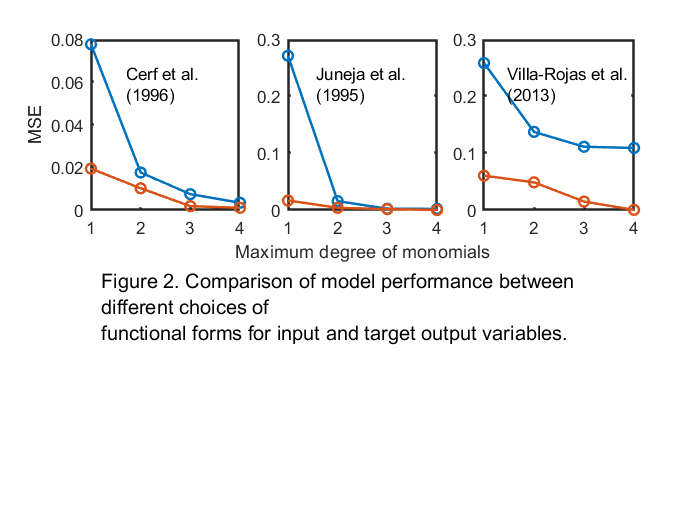

        Xi = sparsifyDynamics(Theta,ObservedD,0);

		EstimatedD = Theta * Xi; %Case 1's estimated D
		PositiveEstimatedD_Idx = EstimatedD >= 0; %Get where the estimated D values are positive
		EstimatedD = log10(EstimatedD(PositiveEstimatedD_Idx)); %Get the log10 of the positive estimated D
		ObservedD = log10(ObservedD(PositiveEstimatedD_Idx)); %Only use the corresponding D values

		%Calculating the MSE for Case 1. Output variable is D. Input terms left as is.
		PlotTheseValues(thePolyorder,1) = ((norm(ObservedD - EstimatedD ) )^2)/length(ObservedD); %ObservedD's length would be reduced since some entries were removed

		%True means temperature has been replaced with 1/temperature		
		[~,Theta] = poolDataFxn(InputVariables,thePolyorder, EveryDataset(ED_Idx).Name, true);

		ObservedD = EveryDataset(ED_Idx).Table{:,1};
		%The log10 D signifies Case 2's output variable is log10(D). ObservedD itself is unchanged.
		Xi = sparsifyDynamics(Theta, log10(ObservedD) ,0);		
		
		%Calculating the MSE for Case 2. Output variable is log D. Temperature was replaced with 1/temperature.
		PlotTheseValues(thePolyorder,2) = (norm(log10(ObservedD) - (Theta * Xi) )^2)/length(EveryDataset(ED_Idx).Table.D);
	end
	subplot(2,3, ED_Idx);
	axis('square')
	plot(PlotTheseValues, 'o-','LineWidth',1.5);
	set(gca,'linewidth',1.5)
	set(gca,'FontSize',10)
% 	TheAnnotations(ED_Idx);
	if ED_Idx == 2
		xlabel("Maximum degree of monomials");
	elseif ED_Idx == 1
		ylabel("MSE");
	end
	
	xticks(1:1:4);

end
annotation('textbox',...
    [0.1321 0.418 0.7785 0.083],...
    'String',{'Figure 2. Comparison of model performance between different choices of','functional forms for input and target output variables.'},...
    'LineStyle','none',...
    'FontSize',12,...
    'FitBoxToText','off'); %Figure caption

The figure tells us the MSE in all three datasets is greater in Case 1 than in Case 2, making the latter serve as the groundwork for the results henceforth in this work. It determines what we build the model with, paving the way for the next step to commence building the model itself in a way that balances accuracy and sparsity.

## Determination of the Model's Order of Polynomial and Sparsity Index

The next cell works with the first dataset, the one authored by Cerf et al.

tbl = EveryDataset(1).Table;
x = tbl{:,2:end};
dy = log10(tbl{:,1});
nVars = size(x,2);

The for loop below helps us determine the ideal order of polynomial for the model. This is based on the MSE values and the number of nonzero terms in the model equation, both of which we seek to minimize. A smaller MSE means the predictions are more accurate. The lower the quantity of nonzero terms, the more interpretable the resulting equation is and easier to act upon, for the fewer factors present and left to consider are determined to have a greater effect on the output. The former and latter expected to decrease and increase respectively as the order of polynomial increases, since as it increases, so too do the library's terms and the model's ability to tune its predictions and make them more accurate, which also means the MSE would be small. Choosing the ideal order of polynomial means balancing the need for accurate predictions (what a small MSE offers) and model sparsity (what a small number of nonzero terms offers).

tableMSE = [0 0 0 0];
nonZeroTerms = tableMSE;
for thePolyorder = 1:4  
    [~,Theta] = poolDataFxn(x,thePolyorder, "Cerf", true);
    Xi = sparsifyDynamics(Theta,dy,0);
    nonZeroTerms(thePolyorder) = length(find(abs(Xi)>eps));
    dyEst=Theta*Xi;
    tableMSE(thePolyorder) = (1/height(tbl))*(norm(dy-dyEst)^2);
end
tableMSE

tableMSE =     0.0193    0.0102    0.0018    0.0010


nonZeroTerms

nonZeroTerms =      4    10    19    27


From the values in tableMSE and nonZeroTerms, the values do indeed decrease and increase as the order of polynomial increases. However, the MSE did not decrease as much when the order of polynomial progressed from equaling 3 to 4. We therefore choose the former value as the ideal order of polynomial because further increments of the order of polynomial, which brings with it additional nonzero terms, will yield diminishing returns to accuracy and violate model sparsity.

The next step focuses on tracking the MSE and number of nonzero terms as the model becomes increasingly sparse, which is accomplished by incrementally increasing the sparsity index, represented here by a lambda. Recall that if any term that would be present in the model equation has a coefficient less than the lambda, then that term is removed from future consideration of inclusion in the equation and future sparse regressions will be conducted without it. Fewer terms lead to the model's diminished ability to affect predictions, making them less accurate and increasing MSE as lambda increases. The ideal sparsity index is one that occurs just before a sharp increase in MSE, which is typically also where a sharp decrease in the number of nonzero terms occurs, since further removal of terms would produce too-costly accuracy reductions.

[xout,Theta] = poolDataFxn(x,3, "Cerf", true);
TheErrorValues = zeros(4/0.08,1);
TheNZTs = TheErrorValues;
for lambda = 0:0.08:4
	Xi = sparsifyDynamics(Theta,dy,lambda);
	dyEst=Theta*Xi;
    Index = round(lambda/0.08 + 1);
	TheErrorValues(Index) = (1/length(tbl.D))*(norm(dy-dyEst)^2); % Mean squared error
	TheNZTs(Index) = sum(abs(Xi) > 0);
end

%Plotting the figure
myFig = figure;
subplot(2,2,[1,3],'Position',[0.13 0.2595 0.3346 0.6473]);

plot(1:4,tableMSE,'-','MarkerSize',8,'Color',[0.8500, 0.3250, 0.0980],'LineWidth',3)
hold on
plot(1:4,tableMSE,'o','MarkerSize',8,'Color',[0.8500, 0.3250, 0.0980],'LineWidth',1.5)
set(gca,'FontSize',13,'linewidth',1.5)
text(1.7,0.014,'\lambda = 0','FontSize',13)
text(1.1,0.001,'Cerf et al. (1996)','FontSize',13)
xline(3,'--k','LineWidth',2)
% title('(a)')
ylabel('MSE')
xlabel('Maximum degree of terms')

subplot(2,2,2,'Position',[0.5678 0.619 0.3371 0.2878])

plot(0:0.08:4,TheErrorValues,'-','MarkerSize',8,'Color',[0.8500, 0.3250, 0.0980], 'LineWidth',3)
hold on
plot(0:0.08:4,TheErrorValues,'o','MarkerSize',8,'Color',[0.8500, 0.3250, 0.0980], 'LineWidth',1.5)
set(gca,'FontSize',13,'linewidth',1.5)
text(1.42,0.004,'\lambda = 1.36','FontSize',13)
xline(1.36,'--k','LineWidth',2)
axis([0 4 0 0.015])
% title('(b)')
ylabel('MSE')
xlabel('\lambda')

subplot(2,2,4,'Position',[0.5703 0.2571 0.3346 0.2785])

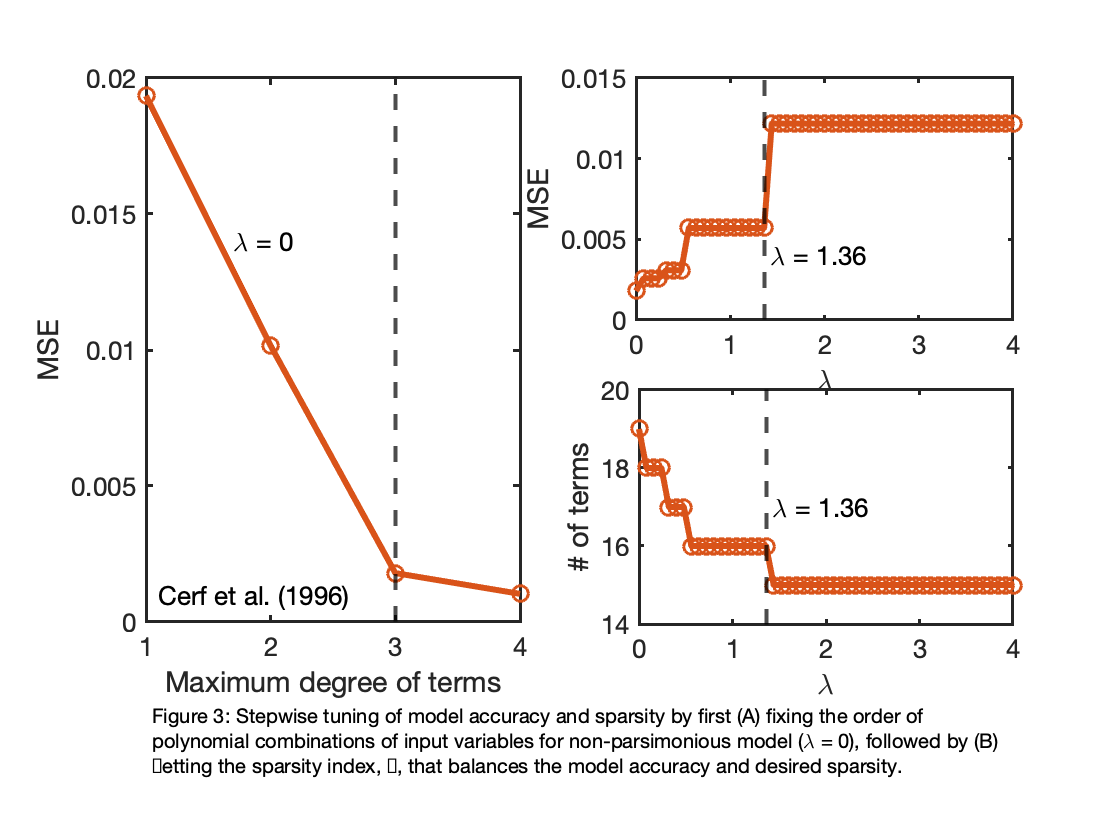

plot(0:0.08:4,TheNZTs,'-','MarkerSize',8,'Color',[0.8500, 0.3250, 0.0980], 'LineWidth',3)
hold on
plot(0:0.08:4,TheNZTs,'o','MarkerSize',8,'Color',[0.8500, 0.3250, 0.0980], 'LineWidth',1.5)
axis([0 4 14 20])
text(1.42,17,'\lambda = 1.36','FontSize',13)
set(gca,'FontSize',13,'linewidth',1.5)
xline(1.36,'--k','LineWidth',2)
ylabel('# of terms')
xlabel('\lambda')


annotation('textbox',...
    [0.1266,0.1127,0.7784,0.0575],...
    'String',{'Figure 3. Stepwise tuning of model accuracy and sparsity by first (A) fixing the order of polynomial combinations of input variables for non-parsimonious model (\lambda = 0), followed by (B) setting the sparsity index, 𝜆, that balances the model accuracy and desired sparsity.'},...
    'FontSize',10,...
    'FitBoxToText','off',...
    'EdgeColor','none');

After determining the ideal order of polynomial and sparsity index in each dataset, we can compare the model's performance against those from the literature.

## Performance Comparison with Existing Models

The structs from earlier, initially containing data contained in the Excel sheet, has been extended with additional info, namely their ideal order of polynomial, sparsity index, and their "Name", which will be used to determine the behavior of `poolDataFxn`. 

AllThreeStructs = [struct('Table',EveryDataset(1).Table,'Polyorder',3,'Lambda',1.36, 'Name', "Cerf"),...
struct('Table',EveryDataset(2).Table,'Polyorder',2,'Lambda',.24, 'Name', "Juneja"),...
struct('Table',EveryDataset(3).Table,'Polyorder',3,'Lambda',174, 'Name', "Villa-Rojas")];
AllThreeStructs(2).Table.CN = AllThreeStructs(2).Table.CN/100; %Need to make these conversions
AllThreeStructs(2).Table.CP = AllThreeStructs(2).Table.CP/100;


`OrigEqn` contains the D values predicted by the model equations found in the literature.

OrigEqn = [struct('ExistingModelD',log10(log(10) ./ (exp( 86.49.*ones(length(AllThreeStructs(1).Table.D),1) - (30280./(AllThreeStructs(1).Table.T + 273.15))...
    - (0.5470.*AllThreeStructs(1).Table.pH) + (.0494.*(AllThreeStructs(1).Table.pH.^2)) + 3.067.*(AllThreeStructs(1).Table.aw.^2) )*60) )),...
struct('ExistingModelD', log10(exp(-9.9161 + (.6159 .* AllThreeStructs(2).Table.T) - (2.8600 .* AllThreeStructs(2).Table.pH)...
- (.2190 .* AllThreeStructs(2).Table.CN) + (2.7424 .* AllThreeStructs(2).Table.CP)...
         +(.0240 .* AllThreeStructs(2).Table.T .* AllThreeStructs(2).Table.pH) - (0.0041 .* AllThreeStructs(2).Table.T .* AllThreeStructs(2).Table.CN)...
         - (0.0611 .* AllThreeStructs(2).Table.T .* AllThreeStructs(2).Table.CP) +(.0443 .* AllThreeStructs(2).Table.pH .* AllThreeStructs(2).Table.CN) + ...
         (0.2937 .* AllThreeStructs(2).Table.pH .* AllThreeStructs(2).Table.CP) - (0.2705 .* AllThreeStructs(2).Table.CN .* AllThreeStructs(2).Table.CP)...
         -(.0053 .* (AllThreeStructs(2).Table.T .^ 2)) + (.1074 .* (AllThreeStructs(2).Table.pH .^ 2)) + ...
         (.0564 .* (AllThreeStructs(2).Table.CN .^ 2)) - (2.7678 * (AllThreeStructs(2).Table.CP .^ 2))))),...
struct('ExistingModelD',-296.569+(607.617.* AllThreeStructs(3).Table.aw)+(6.444.*AllThreeStructs(3).Table.T)...
         -(270.392.*(AllThreeStructs(3).Table.aw .^ 2))-(.030.*(AllThreeStructs(3).Table.T.^2))-(11.580.*AllThreeStructs(3).Table.aw.*AllThreeStructs(3).Table.T)...
    +(3.894*(AllThreeStructs(3).Table.aw .^ 2).*AllThreeStructs(3).Table.T)+(.039.*AllThreeStructs(3).Table.aw.*(AllThreeStructs(3).Table.T.^2)))];

OurRSquared = zeros(1,length(AllThreeStructs)); %Contain our model's R-squared values
TheirRSquared = OurRSquared; %Contains literature's model's R-squared values

containsDyEst = [struct('dyEst',0),struct('dyEst',0),struct('dyEst',0)];

This loop features R-squared values between the predicted and observed D-values and our model's predictions of the D values. It generates higher order polynomials up to the provided `Polyorder` and multiplies by the array of coefficients furnished by `sparsifyDynamics` to create our model's predicted D values.

for Idx = 1:length(AllThreeStructs)
	theLog10D = log10(AllThreeStructs(Idx).Table{:,1});
	[~,Theta] = poolDataFxn(AllThreeStructs(Idx).Table{:,2:end}, AllThreeStructs(Idx).Polyorder, AllThreeStructs(Idx).Name, true);
    Xi = sparsifyDynamics(Theta, theLog10D, AllThreeStructs(Idx).Lambda);
	containsDyEst(Idx).dyEst = Theta * Xi;
	OurRSquared(Idx) = fitlm(theLog10D,containsDyEst(Idx).dyEst).Rsquared.Ordinary;
	TheirRSquared(Idx) = fitlm(theLog10D,OrigEqn(Idx).ExistingModelD).Rsquared.Ordinary;
end
OurRSquared

OurRSquared =     0.9251    0.9698    0.9324


TheirRSquared

TheirRSquared =     0.8112    0.8955    0.3159


Our model's R-squared are consistently higher than that of the literature's. The high values mean the predictions are able to explain almost all of the observed D-values' variability.

myFig = figure;
theFontSize = 9;

subplot(3,2,1,'Position',[0.13,0.7,0.3347,0.2219])

plot(containsDyEst(1).dyEst,log10(AllThreeStructs(1).Table{:,1}),'o','MarkerSize',8,'LineWidth',1.5,'Color', [0.8500 0.3250 0.0980])
hold on
plot(log10(AllThreeStructs(1).Table{:,1}),log10(AllThreeStructs(1).Table{:,1}),'k','LineWidth',3)
text(-0.5,0.7,'Cerf et al. (1996)','FontSize',theFontSize,'Color',[0 0 0])
text(-0.5,0.5,'{\itR}^{2} = 0.925','FontSize',theFontSize,'Color',[0.8500, 0.3250, 0.0980])
% axis equal
axis([-0.6 0.8 -0.6 0.8])
xticks(-0.5:0.3:0.7)
yticks(-0.5:0.3:0.7)
set(gca,'FontSize',13,'linewidth',1.5)

subplot(3,2,2,'Position',[0.57,0.7,0.3347,0.2219])

plot(OrigEqn(1).ExistingModelD,log10(AllThreeStructs(1).Table{:,1}),'o', 'MarkerSize',8,'LineWidth',1.5)
hold on
plot(log10(AllThreeStructs(1).Table{:,1}),log10(AllThreeStructs(1).Table{:,1}),'k','LineWidth',3)
text(-0.5,0.5,'{\itR}^{2} = 0.811','FontSize',theFontSize,'Color',[0, 0.4470, 0.7410])
% axis equal
axis([-0.6 0.8 -0.6 0.8])
xticks(-0.5:0.3:0.7)
yticks(-0.5:0.3:0.7)
set(gca,'FontSize',13,'linewidth',1.5)

subplot(3,2,3,'Position',[0.13,0.4405,0.3347,0.1952])

plot(containsDyEst(2).dyEst,log10(AllThreeStructs(2).Table{:,1}),'o','MarkerSize',8,'LineWidth',1.5,'Color', [0.8500 0.3250 0.0980])
hold on
plot(log10(AllThreeStructs(2).Table{:,1}),log10(AllThreeStructs(2).Table{:,1}),'k','LineWidth',3)
text(0.5,1.7,'Juneja et al. (1995)','FontSize',theFontSize,'Color',[0 0 0])
text(0.5,1.5,'{\itR}^{2} = 0.970','FontSize',theFontSize,'Color',[0.8500, 0.3250, 0.0980])
% axis equal
axis([0.4 1.8 0.4 1.8])
xticks(0.4:0.4:1.8)
yticks(0.4:0.4:1.8)
set(gca,'FontSize',13,'linewidth',1.5)

subplot(3,2,4,'Position',[0.57,0.4405,0.3347,0.1952])

plot(OrigEqn(2).ExistingModelD,log10(AllThreeStructs(2).Table{:,1}),'o', 'MarkerSize',8,'LineWidth',1.5)
hold on
plot(log10(AllThreeStructs(2).Table{:,1}),log10(AllThreeStructs(2).Table{:,1}),'k','LineWidth',3)
text(0.5,1.5,'{\itR}^{2} = 0.970','FontSize',theFontSize,'Color',[0, 0.4470, 0.7410])
% axis equal
axis([0.4 1.8 0.4 1.8])
xticks(0.4:0.4:1.8)
yticks(0.4:0.4:1.8)
set(gca,'FontSize',13,'linewidth',1.5)


subplot(3,2,5,'Position',[0.13,0.1643,0.3347,0.2071])

plot(containsDyEst(3).dyEst,log10(AllThreeStructs(3).Table{:,1}),'o','MarkerSize',8,'LineWidth',1.5,'Color', [0.8500 0.3250 0.0980])
hold on
plot(log10(AllThreeStructs(3).Table{:,1}),log10(AllThreeStructs(3).Table{:,1}),'k','LineWidth',3)
text('FontSize',theFontSize,'String','Villa-Rojas et al. (2013)',...
    'Position',[-1.304 1.284 0]);
text('FontSize',theFontSize,'String','{\itR}^{2} = 0.932',...
    'Position',[-1.304 0.898 0],...
    'Color',[0.85 0.325 0.098]);
% axis equal
axis([-1.5 1.5 -1.5 1.5])
xticks(-1.5:1:1.5)
yticks(-1.5:1:1.5)
set(gca,'FontSize',13,'linewidth',1.5)

subplot(3,2,6,'Position',[0.57,0.1643,0.3347,0.2071])

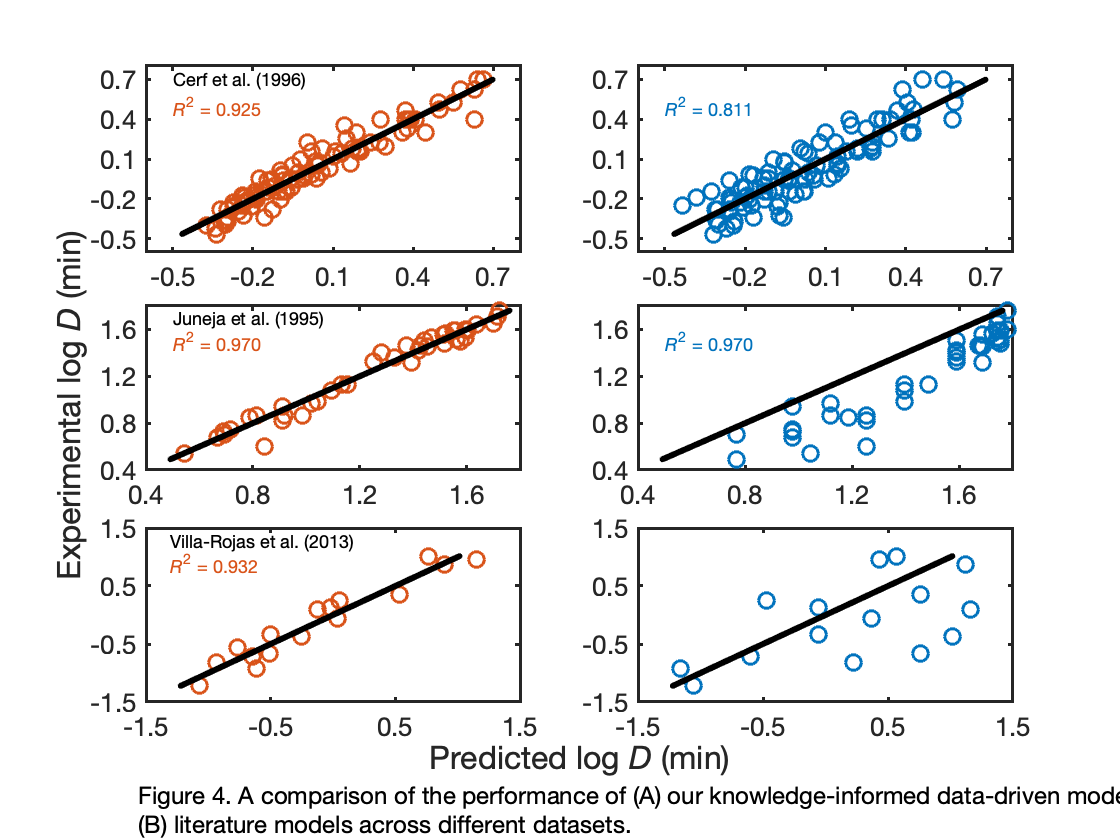

plot(OrigEqn(3).ExistingModelD,log10(AllThreeStructs(3).Table{:,1}),'o', 'MarkerSize',8,'LineWidth',1.5)
hold on
plot(log10(AllThreeStructs(3).Table{:,1}),log10(AllThreeStructs(3).Table{:,1}),'k','LineWidth',3)
% axis equal
axis([-1.5 1.5 -1.5 1.5])
xticks(-1.5:1:1.5)
yticks(-1.5:1:1.5)
set(gca,'FontSize',13,'linewidth',1.5)

han=axes(myFig,'visible','off'); 
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylh = ylabel(han,"Experimental log {\itD} (min)",'FontSize', 16);
xlh = xlabel(han,"Predicted log {\itD} (min)",'FontSize', 16);
xlh.Position(2) = xlh.Position(2)+0.065;
ylh.Position(1) = ylh.Position(1)-0.02;

annotation('textbox',...
    [0.1142 0.024 0.999 0.0535],...
    'String',{'Figure 4. A comparison of the performance of (A) our knowledge-informed data-driven models against (B) literature models across different datasets.'},...
    'FontSize',12,...
    'EdgeColor','none');

The closer a point's x and y value are the closer the predictions are to the observed D values. The figures in the left half presents the points having much greater overlap with the black line, a portion of a line with slope 1 and x-intercept of 0, than those on the right, which indicates how much closer our model's predictions are to the observed D than the literatures' predictions. Users are free to observe how well our model performs with different order of polynomials and sparsity indices should the above fail to satisfy accuracy and/or sparsity standards.

The model equations often showcase the effects combinations of variables have on D-value predictions, meaning there's more to learn about how to evaluate the effects of individual variables.

## Evaluating Individual Process Variables' Influence on Output with Global Sensitivity Analysis

load PAWN_GSA_Results.mat

The above cell stores the results of the Kolmogorov-Smirnov (KS) test, which calculates the distance between distribution functions, like empirical and cumulative ones, in a MAT file. The file's contents provide the foundation of the boxplots plotted below. Those adorned with an asterisk were found to have significant influence on the predictions.

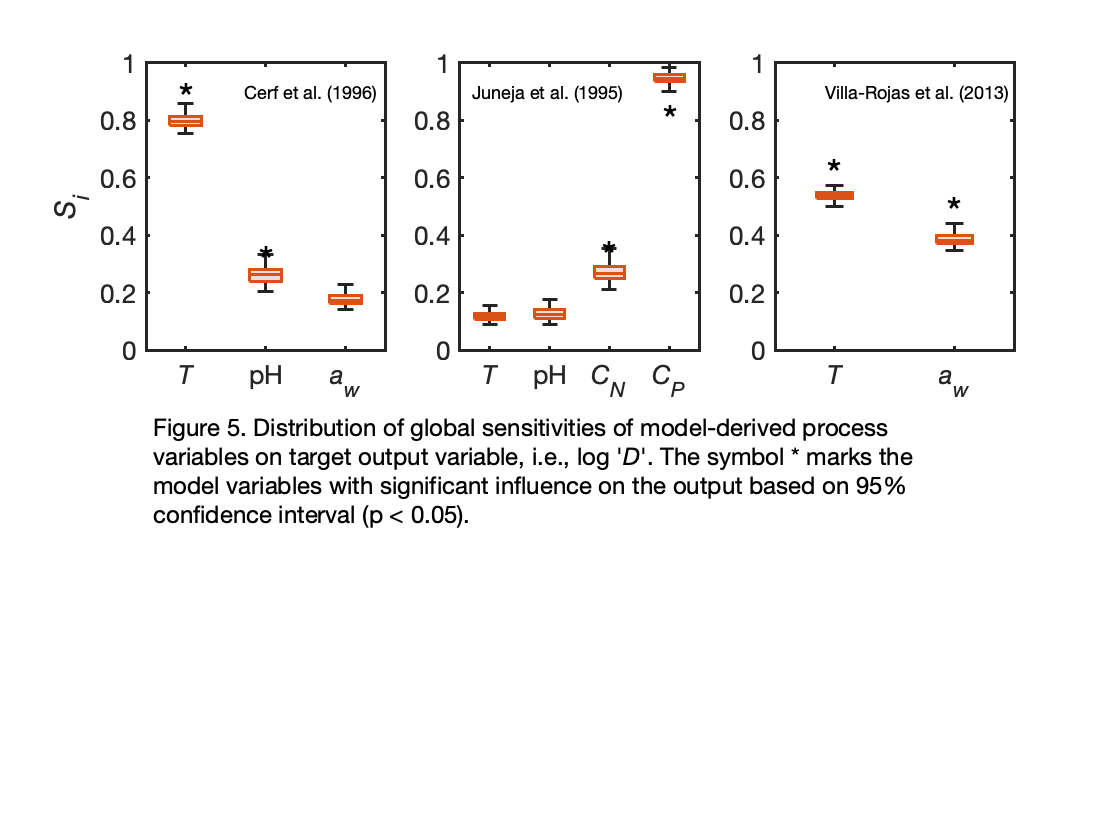

theFontSize = 9;

fig = figure;
subplot(2,3,1)
b = boxchart(Ti{1},'boxfacecolor',[0.8500, 0.3250, 0.0980]);
b.MarkerStyle = 'none';
b.LineWidth = 1.5;
b.BoxWidth = 0.4;
set(gca,'FontSize',13,'linewidth',1.5)
box on
xticklabels({'\itT','pH','\ita_{w}'})
ylabel('\itS_{i}')
text('FontSize',20,'String','*',...
    'Position',[0.9090,0.88,0]);
text('FontSize',20,'String','*',...
    'Position',[1.9190,0.3148,0]);

text('FontSize',theFontSize,'String','Cerf et al. (1996)',...
    'Position',[1.7283 0.9 0]);
yticks(0:0.2:1)
ylim([0 1])

subplot(2,3,2)
b = boxchart(Ti{2},'boxfacecolor',[0.8500, 0.3250, 0.0980]);
b.MarkerStyle = 'none';
b.LineWidth = 1.5;
% b.BoxWidth = 0.25;
set(gca,'FontSize',13,'linewidth',1.5)
box on
xticklabels({'\itT','pH','\itC_{N}','\itC_{P}'})
text('FontSize',20,'String','*',...
    'Position',[2.872,0.33,0]);
text('FontSize',20,'String','*',...
    'Position',[3.892,0.8051,0]);
text(0.7,0.9,'Juneja et al. (1995)','FontSize',theFontSize)
yticks(0:0.2:1)
ylim([0 1])

subplot(2,3,3)
b = boxchart(Ti{3},'boxfacecolor',[0.8500, 0.3250, 0.0980]);
b.MarkerStyle = 'none';
b.LineWidth = 1.5;
b.BoxWidth = 0.3;
set(gca,'FontSize',13,'linewidth',1.5)
box on
xticklabels({'\itT','\ita_{w}'})
ylim([0 1])
text('FontSize',20,'String','*',...
    'Position',[0.9325,0.6164,0]);
text('FontSize',20,'String','*',...
    'Position',[1.9425,0.4830,0]);
text('FontSize',theFontSize,'String','Villa-Rojas et al. (2013)',...
    'Position',[0.9193,0.9,0]);
yticks(0:0.2:1)
ylim([0 1])
annotation('textbox',...
    [0.1274 0.4616 0.7291 0.0535],...
    'String',{'Figure 5. Distribution of global sensitivities of model-derived process variables on target output variable, i.e., log ''{\itD}''. The symbol * marks the model variables with significant influence on the output based on 95% confidence interval (p < 0.05).'},...
    'FontSize',12,...
    'FitBoxToText','off',...
    'EdgeColor','none');


% han=axes(fig,'visible','off'); 
% han.XLabel.Visible='on';
% xlh = xlabel(han,'Process variables','FontSize',13);
% xlh.Position(2) = xlh.Position(2)-0.03;

But just because a variables lacks an asterisk, it doesn't preclude them from exercising signficant influence in other ways. Next, we evaluate the influence that individual polynomials in the model equations have on the output.

## Evaluating Individual Polynomial Terms' Effects on Predictions

for StructIdx = 1:length(AllThreeStructs)
    
	theLog10D = log10(AllThreeStructs(StructIdx).Table.D);

	[xout,Theta] = poolDataFxn(AllThreeStructs(StructIdx).Table{:,2:end}, AllThreeStructs(StructIdx).Polyorder, AllThreeStructs(StructIdx).Name, true);
	Xi = sparsifyDynamics(Theta, theLog10D, AllThreeStructs(StructIdx).Lambda);
	xout(abs(Xi) > eps)

	KeepTheseTerms = abs(Xi) > eps;
	Theta = Theta(:, KeepTheseTerms);
	Xi = Xi(KeepTheseTerms);
    

In `Xi`, terms where the sparsity index exceeded them were made equal to 0 and the indices of those exceeding the index were stored. These terms map to the ones found in the final model equation.

Then, we iterate through a dataset's model equation, remove one term from a copt of the model equation, and calculate the MSE.

	
	PlotTheseValues = zeros(1,length(Xi));
	for VariableIdx = 1:length(Xi)
		copyTheta = Theta;
		copyXi = Xi;
		copyTheta(:, VariableIdx) = []; %Remove VariableIdx'th variable from the equation
		copyXi(VariableIdx) = [];
		PlotTheseValues(VariableIdx) = (norm(theLog10D - (copyTheta * copyXi)  )^2) / length(theLog10D);
		
    end
    TAB{StructIdx} = PlotTheseValues';
end

$$ans = \left(\begin{array}{cccccccccccccccc} 1 & x_{1} & x_{2} & \frac{1}{x_{3}} & x_{1}\,x_{2} & \frac{x_{1}}{x_{3}} & \frac{x_{2}}{x_{3}} & \frac{1}{{x_{3}}^{2}} & {x_{1}}^{3} & {x_{1}}^{2}\,x_{2} & \frac{{x_{1}}^{2}}{x_{3}} & \frac{x_{1}\,x_{2}}{x_{3}} & \frac{x_{1}}{{x_{3}}^{2}} & \frac{{x_{2}}^{2}}{x_{3}} & \frac{x_{2}}{{x_{3}}^{2}} & \frac{1}{{x_{3}}^{3}} \end{array}\right)$$

$$ans = \left(\begin{array}{cccccccccccccc} 1 & \frac{1}{x_{1}} & x_{2} & x_{3} & x_{4} & \frac{1}{{x_{1}}^{2}} & \frac{x_{2}}{x_{1}} & \frac{x_{3}}{x_{1}} & \frac{x_{4}}{x_{1}} & x_{2}\,x_{3} & x_{2}\,x_{4} & {x_{3}}^{2} & x_{3}\,x_{4} & {x_{4}}^{2} \end{array}\right)$$

$$ans = \left(\begin{array}{ccccccc} \frac{1}{x_{2}} & \frac{x_{1}}{x_{2}} & \frac{1}{{x_{2}}^{2}} & {x_{1}}^{3} & \frac{{x_{1}}^{2}}{x_{2}} & \frac{x_{1}}{{x_{2}}^{2}} & \frac{1}{{x_{2}}^{3}} \end{array}\right)$$


fig = figure;
subplot(3,1,1, 'Position',[0.13,0.7553,0.775,0.1697])

bar(TAB{1},0.5,'FaceColor',[0.8500, 0.3250, 0.0980],'EdgeColor','none','FaceAlpha',0.8)
xticks(1:length(TAB{1}))
xticklabels({'1','{\ita_w}','pH','{\it1/T}','{\ita_w}pH','{\ita_w/T}','{pH/\itT}','{\it1/T^2}','{\ita_w^3}','{\ita_w^2}pH','{\ita_w^2/T}','{\it(a_w}pH)/{\itT}','{\ita_w/T^2}','pH^2/{\itT}','pH/{\itT^2}','1/{\itT^3}'});
axis([0 length(TAB{1})+1 0 8e5])
text(13,6e5,'Cerf et al. (1996)','FontSize',13)
set(gca,'FontSize',11,'linewidth',1.2)

subplot(3,1,2, 'Position',[0.13,0.4961,0.775,0.1604])

bar(TAB{2},0.5,'FaceColor',[0.8500, 0.3250, 0.0980],'EdgeColor','none','FaceAlpha',0.8)
xticks(1:length(TAB{2}))
xticklabels({'1', '{\it1/T}', 'pH', '{\itC_N}', '{\itC_P}', '{\it1/T^2}', 'pH/{\itT}', '{\itC_N/T}', '{\itC_P/T}', 'pH{\itC_N}', 'pH{\itC_P}', '{\itC_N^2}', '{\itC_NC_P}', '{\itC_P^2}'});
axis([0 length(TAB{2})+1 0 2000])
text(11,1500,'Juneja et al. (1995)','FontSize',13)
set(gca,'FontSize',11,'linewidth',1.2)

subplot(3,1,3, 'Position',[0.13,0.2488,0.775,0.1604])

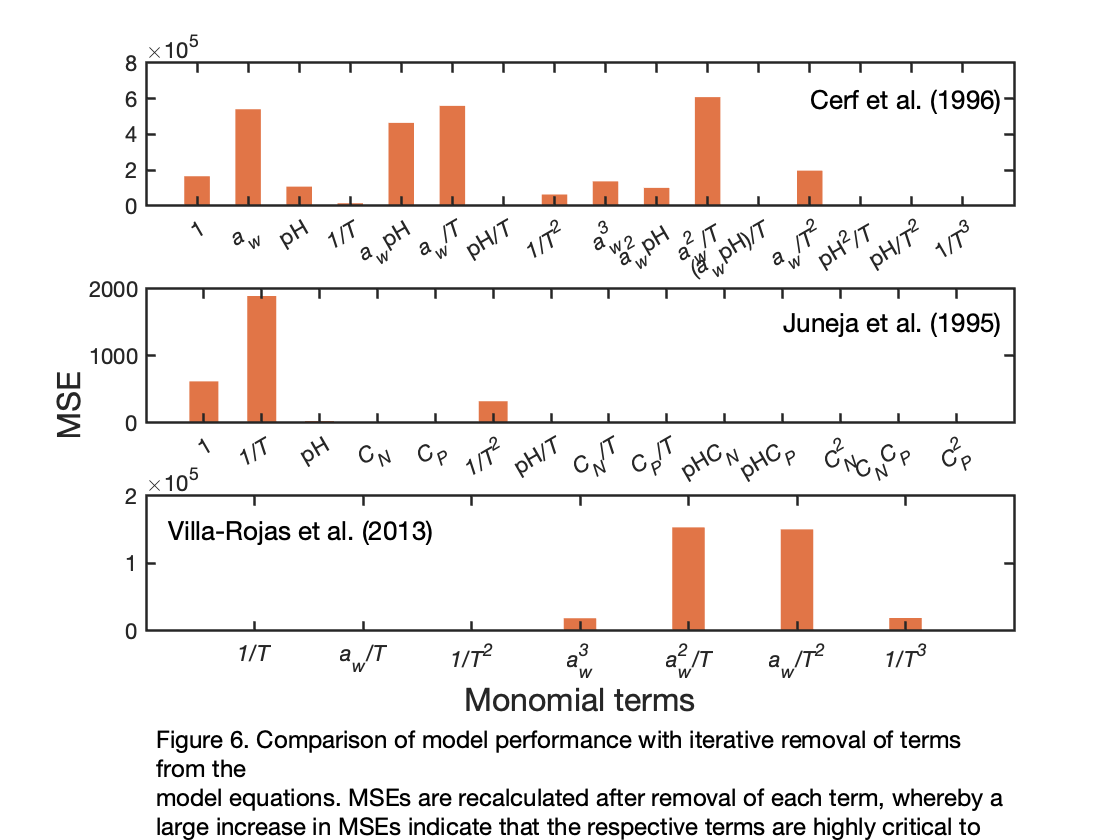

bar(TAB{3},0.3,'FaceColor',[0.8500, 0.3250, 0.0980],'EdgeColor','none','FaceAlpha',0.8)
xticks(1:length(TAB{3}))
xticklabels({'{\it1/T}', '{\ita_w/T}', '{\it1/T^2}', '{\ita_w^3}', '{\ita_w^2/T}', '{\ita_w/T^2}', '{\it1/T^3}'});
axis([0 length(TAB{3})+1 0 20e4])
text(0.2,1.5e5,'Villa-Rojas et al. (2013)','FontSize',13)
set(gca,'FontSize',11,'linewidth',1.2)

annotation('textbox',...
    [0.13 0.0732 0.7767 0.071],...
    'String',{'Figure 6. Comparison of model performance with iterative removal of terms from the','model equations. MSEs are recalculated after removal of each term, whereby a','large increase in MSEs indicate that the respective terms are highly critical to','represent the output data.'},...
    'FontSize',12,...
    'FitBoxToText','off',...
    'EdgeColor','none');

han=axes(fig,'visible','off'); 
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylh = ylabel(han,"MSE",'FontSize', 16);
xlh = xlabel(han,"Monomial terms",'FontSize', 16);
xlh.Position(2) = xlh.Position(2)+0.15;
ylh.Position(1) = ylh.Position(1)-0.02;

From the bar chart, a MSE close to 0 means the removal of that term barely or didn't increase it at all, meaning it doesn't have much influence. Yet there are several terms whose removal did lead to large increases. Although water activity from the Cerf et al. dataset wasn't deemed significant, several of its terms here would greatly increase MSE in their absence. Individual effects alone may be insufficient to produce accurate predictions; supplementing the effects of their interaction with other process variables should bolster accuracy. 